addpath("C:\Users\roboime\Desktop\RoboCup Arm_Challenge RoboIME")
clear; clc; close all;
pause(3);
rosIP = "192.168.187.128"; 
rosshutdown;

Shutting down global node /matlab_global_node_10413 with NodeURI http://192.168.187.1:50458/ and MasterURI http://192.168.187.128:11311.


pause(3);
rosinit(rosIP,11311);

Initializing global node /matlab_global_node_90041 with NodeURI http://192.168.187.1:50581/ and MasterURI http://192.168.187.128:11311.



[trajAct,trajGoal] = rosactionclient('/pos_joint_traj_controller/follow_joint_trajectory','control_msgs/FollowJointTrajectory','DataFormat','struct');
trajAct.FeedbackFcn = []; 
trajAct.ResultFcn = []; 

[gripAct, gripGoal] = rosactionclient('/gripper_controller/follow_joint_trajectory', 'control_msgs/FollowJointTrajectory', 'DataFormat', 'struct');
gripAct.FeedbackFcn = [];
gripAct.ResultFcn = [];
waitForServer(gripAct);

cinematica_inversa_colisao([0.4 0.4  0.4],trajAct,trajGoal)

tformBase =    -1.0000    0.0000   -0.0000   -0.1000
   -0.0000   -1.0000   -0.0000    0.0000
   -0.0000   -0.0000    1.0000         0
         0         0         0    1.0000


% % Carrega o modelo
% UR5e = loadrobot('universalUR5e');
% 
% % Define a pose desejada
% config = homeConfiguration(UR5e);
% config(1).JointPosition = 0;         % shoulder_pan_joint
% config(2).JointPosition = -pi/2;     % shoulder_lift_joint
% config(3).JointPosition = 0;         % elbow_joint
% config(4).JointPosition = 0;         % wrist_1_joint
% config(5).JointPosition = -pi/2;     % wrist_2_joint
% config(6).JointPosition = 0;         % wrist_3_joint
% 
% % Armazena as transformações desejadas antes de fixar as juntas
% T1 = getTransform(UR5e, config, 'wrist_1_link', 'forearm_link');
% T2 = getTransform(UR5e, config, 'wrist_2_link', 'wrist_1_link');
% T3 = getTransform(UR5e, config, 'wrist_3_link', 'wrist_2_link');
% 
% % Cria juntas fixas com as transformações obtidas
% J1 = rigidBodyJoint('fixed_wrist_1','fixed');
% setFixedTransform(J1, T1);
% 
% J2 = rigidBodyJoint('fixed_wrist_2','fixed');
% setFixedTransform(J2, T2);
% 
% J3 = rigidBodyJoint('fixed_wrist_3','fixed');
% setFixedTransform(J3, T3);
% 
% % Substitui as juntas revolutas pelas fixas
% replaceJoint(UR5e, 'wrist_1_link', J1);
% replaceJoint(UR5e, 'wrist_2_link', J2);
% replaceJoint(UR5e, 'wrist_3_link', J3);
% 
% config = homeConfiguration(UR5e);
% config(1).JointPosition = 0;        % shoulder_pan_joint
% config(2).JointPosition = -pi/2;    % shoulder_lift_joint
% config(3).JointPosition = 0;        % elbow_joint
% 
% shoulder_pan_joint.PositionLimits = [-pi/2 pi/2];  
% shoulder_lift_joint.PositionLimits = [0 pi]; 
% elbow_joint.PositionLimits = [-pi pi];
% 
% % % Visualiza o novo modelo
% % show(UR5e, config);
% % showdetails(UR5e);

% % Assumindo que UR5e já foi modificado com as juntas wrist fixas
% 
% % Criação do solver de cinemática inversa
% ik = inverseKinematics("RigidBodyTree", UR5e);
% 
% % Pesos para [x y z roll pitch yaw]
% ikWeights = [1 1 1 0 0 0];  

% % Geração da matriz de transformação alvo
% tform = trvec2tform(targetPosition') * quat2tform(targetOrientation);
% 
% % Criação de palpite inicial (guess) com apenas 3 juntas
% initialGuess(1).JointPosition = jointStateMsg.Position(4);  % shoulder_pan_joint
% initialGuess(2).JointPosition = jointStateMsg.Position(3);  % shoulder_lift_joint
% initialGuess(3).JointPosition = jointStateMsg.Position(1);  % elbow_joint
% 
% % Executa a cinemática inversa
% [configSoln, solnInfo] = ik('tool0', tform, ikWeights, initialGuess);
% 
% % Extrai posições das juntas usadas
% UR5eConfig = [configSoln(1).JointPosition, configSoln(2).JointPosition, configSoln(3).JointPosition];

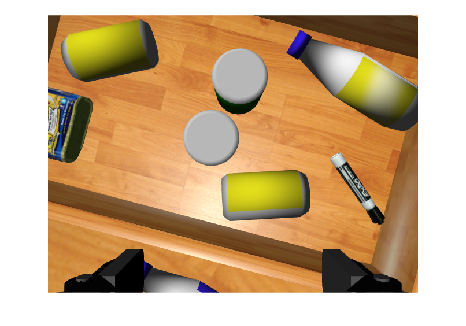

%imagem

rot(0, trajGoal, trajAct)
pause(5)
%carregar imagem
rgbSub   = rossubscriber('/camera/rgb/image_raw',"sensor_msgs/Image","DataFormat","struct");
pause(1)
rgbMsg   = receive(rgbSub,3);
rgbImg   = rosReadImage(rgbMsg);
imshow(rgbImg);


% Verifica as dimensões da imagem
[imgHeight, imgWidth, numChannels] = size(rgbImg);

% Exibe as dimensões
fprintf('Altura: %d pixels\n', imgHeight);

Altura: 480 pixels


fprintf('Largura: %d pixels\n', imgWidth);

Largura: 640 pixels


fprintf('Canais de cor: %d\n', numChannels);

Canais de cor: 3


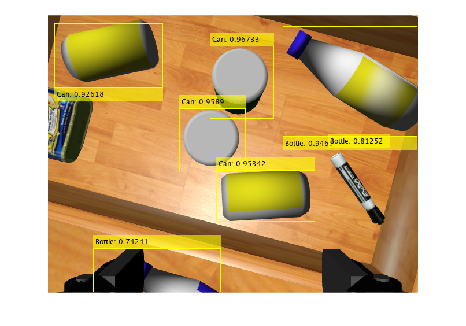


%detecção
load('\Users\roboime\Desktop\RoboCup Arm_Challenge RoboIME\Color_Detector.mat','colorDetector'); 
imTest = rgbImg; 
[dbox,dscore,dlabel] = detect(colorDetector,imTest);
labelsWithScores = string(dlabel) + ": " + string(dscore);
imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);
imshow(imTested);

 pause(2);

%  %Ver dados
%  for i = 1:numel(dlabel)
%     fprintf('Objeto %d:\n', i);
%     fprintf('  Rótulo: %s\n', string(dlabel(i)));
%     fprintf('  Score: %.2f\n', dscore(i));
%     fprintf('  Caixa: [x=%d, y=%d, largura=%d, altura=%d]\n\n', ...
%         dbox(i,1), dbox(i,2), dbox(i,3), dbox(i,4));
% end

 pos_robot = [0.101107, 0.133073, 0.4]

pos_robot =     0.1011    0.1331    0.4000


 idxMaiorScore = analisarMaiorScore(dbox, dscore, dlabel)

Objeto com maior score:
  Rótulo: Can
  Score: 0.97
  Caixa: [x=2.805954e+02, y=5.401275e+01, largura=1.108838e+02, altura=1.259560e+02]


idxMaiorScore = 2

 pos_obj = coordenadas_do_objeto(idxMaiorScore,dbox,pos_robot)

pos_img =   336.0372   -8.9653


pos_img =     0.1510   -0.0040


pos_obj =     0.2522    0.1290



% depthSub = rossubscriber('/camera/depth/image_raw',"sensor_msgs/Image","DataFormat","struct");
% pause(1)
% depthMsg = receive(depthSub,3);
% depthImg = rosReadImage(depthMsg);
% imshow(depthImg);
% 
% addpath('C:\Users\roboime\Downloads\');
% load('C:\Users\roboime\Downloads\Depth_Detector.mat','shapeDetector');
% depthImgNorm = mat2gray(depthImg);  % Normaliza para [0, 1]
% depthImgRGB = uint8(depthImgNorm * 255);  % Converte para imagem tipo uint8
% imTest = repmat(depthImgRGB, 1, 1, 3);  % Converte para 3 canais RGB
% [dbox,dscore,dlabel] = detect(shapeDetector,imTest);
% labelsWithScores = string(dlabel) + ": " + string(dscore);
% imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);
% imshow(imTested);
% pause(7);



% 
% 
%  depthSub = rossubscriber('/camera/depth/image_raw',"sensor_msgs/Image","DataFormat","struct");
% pause(1)
% depthMsg = receive(depthSub,3);
% depthImg = rosReadImage(depthMsg);
% imshow(depthImg);
% 
% 
% addpath('C:\Users\roboime\Downloads\');
% load('C:\Users\roboime\Downloads\Depth_Detector.mat','shapeDetector');
% depthImgNorm = mat2gray(depthImg);  % Normaliza para [0, 1]
% depthImgRGB = uint8(depthImgNorm * 255);  % Converte para imagem tipo uint8
% imTest = repmat(depthImgRGB, 1, 1, 3);  % Converte para 3 canais RGB
% [dbox,dscore,dlabel] = detect(shapeDetector,imTest);
% labelsWithScores = string(dlabel) + ": " + string(dscore);
% imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);
% imshow(imTested);
%  pause(2); 

%  % objeto 1
% pos1 = [-0.362763 -0.10707 0.252];
% tform = eul2tform(gripperRotation); %
% tform(1:3,4) = pos1'; % set translation in homogeneous transform
%  jointStateMsg = receive(jointSub,100); % recebe a configuração atual do robô
%  config_l = [UR5econfig(1) 0 0 0 0 0]; % ângulos iniciais dos elementos do robô
%  k3 = 0.8;
%  k4 = 1.02; % diminuir -> mais fechado.
%  abrir_garra(0, gripGoal, gripAct);
%  abrir_garra(0.5, gripGoal, gripAct);
%  pause(3);
%  config = rotelem(UR5econfig, [0.5 0.14 1 1 1 1], [1 2 3 4 5 6], jointSub, trajGoal, trajAct, 7);
%  ajuste(config, 4, 0.28, 2, jointSub, trajGoal, trajAct, 5);
%  pause(4);
%  ajuste(config, 3, 0.7, 3, jointSub, trajGoal, trajAct, .8);
%  pause(5);
%  disp(config_l);
%  abrir_garra(0, gripGoal, gripAct)
%  pause(1);
%  config_l = [0 0 0 0 -.1 0]; 
%  jointStateMsg = receive(jointSub,100); % receive current robot configuration
%  trajGoal = packTrajGoal(config_l,trajGoal, 3);
%  sendGoal(trajAct,trajGoal);
% 

% % objeto 2
% pos2 = [ 0.667331 -0.077456 0.3 ];
% abrir_garra(0, gripGoal, gripAct);
% initialIKGuess(2).JointPosition = 0.05;
% tform = eul2tform(gripperRotation); %
% tform(1:3,4) = pos2'; % set translation in homogeneous transform
% [configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess);
% disp(configSoln)
% UR5econfig = [configSoln(3).JointPosition configSoln(2).JointPosition configSoln(1).JointPosition...
%     configSoln(4).JointPosition configSoln(5).JointPosition configSoln(6).JointPosition];
% pause(3);
% config2 = rotelem(UR5econfig, [1 1 1 1 1.091 1], [5 2 3 4 1 6], jointSub, trajGoal, trajAct, 5);
% pause(10);
% 
% config2 = ajuste(config2, 4, -.04, 5, jointSub, trajGoal, trajAct, 5);% -,035 o anterior
% pause(1);
% config2 = ajuste(config2, 2, -0.06, 5, jointSub, trajGoal, trajAct, 7);
% pause(6);
% abrir_garra(0.237,gripGoal,gripAct);
% pause(10);
% config2 = ajuste(config2, 2, 0.6, 2, jointSub, trajGoal, trajAct, 5);
% config2 = ajuste(config2, 3, -2.3, 3, jointSub, trajGoal, trajAct, 5);
% pause(10);
% abrir_garra(0, gripGoal, gripAct);
% pause(3);
% config_l = [0 0 0 0 0 0]; 
% jointStateMsg = receive(jointSub,100); % receive current robot configuration
% trajGoal = packTrajGoal(config_l,trajGoal, 5);
% sendGoal(trajAct,trajGoal);
% pause(2);

% % % objeto 3
% pos3 = [ 0.460249 -0.170230 .3 ];
% abrir_garra(0.1, gripGoal, gripAct);
% initialIKGuess(2).JointPosition = 0.5;
% initialIKGuess(3).JointPosition = -0.5;
% tform = eul2tform(gripperRotation); %
% tform(1:3,4) = pos3'; % set translation in homogeneous transform
% [configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess);
% disp(configSoln)
% UR5econfig = [configSoln(3).JointPosition configSoln(2).JointPosition configSoln(1).JointPosition...
%     configSoln(4).JointPosition configSoln(5).JointPosition configSoln(6).JointPosition];
% 
% config = rotelem(UR5econfig, [1 1 1 1 1 1], [1 2 3 4 5 6], jointSub, trajGoal, trajAct, 3);
% pause(5);
% config = ajuste(config, 3, .4, 5, jointSub, trajGoal, trajAct, 3);
% pause(2);
% config = ajuste(config, 2, -.3, 5, jointSub, trajGoal, trajAct, 3);
% config = ajuste(config, 4, -.13, 5, jointSub, trajGoal, trajAct, 3);
% config = ajuste(config, 1, -.1, 5, jointSub, trajGoal, trajAct, 3);
% config = ajuste(config, 3, -1.2, 5, jointSub, trajGoal, trajAct, 1);
% pause(3);
% home = [0 0 0 0 0 0];
% trajGoal = packTrajGoal(home, trajGoal, 7);
% sendGoal(trajAct, trajGoal);


%objeto 4
% pos4 = [ -.618982 .220016 .248702];
% abrir_garra(0.1, gripGoal, gripAct);
% initialIKGuess(2).JointPosition = 0.2;
% initialIKGuess(3).JointPosition = 0.5;
% tform = eul2tform(gripperRotation); %
% tform(1:3,4) = pos4'; % set translation in homogeneous transform
% [configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess);
% disp(configSoln)
% UR5econfig = [configSoln(3).JointPosition configSoln(2).JointPosition configSoln(1).JointPosition...
%     configSoln(4).JointPosition configSoln(5).JointPosition configSoln(6).JointPosition];
% config = rotelem(UR5econfig, [1 1 1 1 1 1], [1 2 3 4 5 6], jointSub, trajGoal, trajAct, 5);
% config = ajuste(config, 6, 1.5, 3, jointSub, trajGoal, trajAct, 5);
% config = ajuste(config, 2, 0.23, 3, jointSub, trajGoal, trajAct, 5);
% config = ajuste(config, 4, -.15, 3, jointSub, trajGoal, trajAct, 5);
% pause(3);
% config = ajuste(config, 3, -.03, 3, jointSub, trajGoal, trajAct, 5);
% config = ajuste(config, 2, 0.01, 3, jointSub, trajGoal, trajAct, 5);
% config = ajuste(config, 4, -.05, 3, jointSub, trajGoal, trajAct, 5);
% config = ajuste(config, 3, -.03, 3, jointSub, trajGoal, trajAct, 5);
% config = ajuste(config, 2, 0.02, 3, jointSub, trajGoal, trajAct, 5);
% config = ajuste(config, 4, -.02, 3, jointSub, trajGoal, trajAct, 5);
% config = ajuste(config, 3, -.01, 3, jointSub, trajGoal, trajAct, 5);
% config = ajuste(config, 2, 0.023, 3, jointSub, trajGoal, trajAct, 5);
% abrir_garra(0.211, gripGoal, gripAct);
% pause(5);
% config = ajuste(config, 2, -.5, 3, jointSub, trajGoal, trajAct,10);
% config = ajuste(config, 3 , -3.14, 5 , jointSub, trajGoal, trajAct, 10);
% pause(5);
% abrir_garra(0, gripGoal, gripAct);
% config = ajuste(config, 2, 1.5, 3, jointSub, trajGoal, trajAct,10);
% pause(6);
% config = ajuste(config, 2, -2, 3, jointSub, trajGoal, trajAct, 5);
% pause(3);

% % objeto 5
% abrir_garra(0, gripGoal, gripAct);
% initialIKGuess(2).JointPosition = 0.2;
% initialIKGuess(3).JointPosition = 0.5;
% initialIKGuess(6).JointPosition = 1.5
% tform = eul2tform(gripperRotation); %
% tform(1:3,4) = pos4'; % set translation in homogeneous transform
% [configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess);
% disp(configSoln)
% UR5econfig = [configSoln(3).JointPosition configSoln(2).JointPosition configSoln(1).JointPosition...
%     configSoln(4).JointPosition configSoln(5).JointPosition configSoln(6).JointPosition];
% config = rotelem(UR5econfig, [1 1 1 1.2 1 1], [4 1 3 2 5 6], jointSub, trajGoal, trajAct, 5);
% 
% config = ajuste(config, 3, -.15, 2, jointSub, trajGoal, trajAct, 2);
% pause(5);
% 
% config = ajuste(config, 1, .1, 5, jointSub, trajGoal, trajAct, 5);
% config = ajuste(config, 4, .08, 5, jointSub, trajGoal, trajAct, 5);
% config = ajuste(config, 5, -.05, 5, jointSub, trajGoal, trajAct, 5);
% pause(6);
% abrir_garra(.222, gripGoal, gripAct);%.235 a anterior
% pause(10);
% config = ajuste(config, 2, -.5, 3, jointSub, trajGoal, trajAct, 5);
% config = ajuste(config, 3, +1, 3, jointSub, trajGoal, trajAct, 5);
% pause(5);
% abrir_garra(0, gripGoal, gripAct);

% %objeto 6
% pos6 = [-0.463792 0.346733 0.14]
% abrir_garra(0.1, gripGoal, gripAct);
% initialIKGuess(2).JointPosition = -0.5;
% initialIKGuess(3).JointPosition = +0.5;
% tform = eul2tform(gripperRotation); %
% tform(1:3,4) = pos6'; % set translation in homogeneous transform
% [configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess);
% disp(configSoln)
% UR5econfig = [configSoln(3).JointPosition configSoln(2).JointPosition configSoln(1).JointPosition...
% configSoln(4).JointPosition configSoln(5).JointPosition configSoln(6).JointPosition];
% config = rotelem(UR5econfig, [1 1 1 1 1 1], [4 2 3 1 5 6], jointSub, trajGoal, trajAct, 15);
% config = ajuste(config, 6, -.8, 4, jointSub, trajGoal, trajAct, 6);
% pause(5);
% config = ajuste(config, 2, .03, 4, jointSub, trajGoal, trajAct, 6);
% pause(3);
% abrir_garra(.3, gripGoal, gripAct);%.235 a anterior
% pause(8);
% config = ajuste(config, 2, -.7, 4, jointSub, trajGoal, trajAct, 6);
% pause(3);
% config = ajuste(config, 3, 1 , 4, jointSub, trajGoal, trajAct, 6);
% pause(7);
% abrir_garra(0, gripGoal, gripAct);


% %cub
%  % x aqui é -y no gazebo ; y aqui é x no gazebo ; z mantém
% posc1 = [0.130999 0.520999  0.058];
% posc1(2) = posc1(2) + 0.06
% posc1(1) = posc1(1) - 0.04
% posicao_inicial(trajGoal, trajAct, gripGoal, gripAct);
% jointSub = rossubscriber("/joint_states",'DataFormat','struct');
% jointStateMsg = receive(jointSub,100) % receive current robot configuration
% initialIKGuess(1).JointPosition = jointStateMsg.Position(4); % update configuration in initial guess
% initialIKGuess(2).JointPosition = jointStateMsg.Position(3);
% initialIKGuess(3).JointPosition = jointStateMsg.Position(1);
% initialIKGuess(4).JointPosition = jointStateMsg.Position(5);
% initialIKGuess(5).JointPosition = jointStateMsg.Position(6);
% initialIKGuess(6).JointPosition = jointStateMsg.Position(7);
% tform = eul2tform(gripperRotation); %
% tform(1:3,4) = posc1'; % set translation in homogeneous transform
% [configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess);
% disp(configSoln)
% UR5econfig = [configSoln(3).JointPosition configSoln(2).JointPosition configSoln(1).JointPosition...
%     configSoln(4).JointPosition configSoln(5).JointPosition configSoln(6).JointPosition];
% config = rotelem(UR5econfig, [1 1 1 1 1 1], [4 2 1 3 5 6], jointSub, trajGoal, trajAct);
% rot(0.1, trajGoal, trajAct)
% pause(10)
% abrir_garra(0.5, gripGoal, gripAct);%.235 a anterior
% %lixo(2,trajGoal, trajAct,gripGoal, gripAct)
